cd('/Volumes/PcSSDA/20220422_112_AChmtut_SW_001')
ExperimentName='20220422_112_AChmtut_SW_001'; % Give a specific name to this experiment or this analysis
FirstAcq=13; % What's the acquisition number of the first offical recording
number_of_acq = 23; % How many chunks of recordings are there?
Dark_hours=[13 14 15 16 17 18 19 20 21 22 23 24 25]

Dark_hours =     13    14    15    16    17    18    19    20    21    22    23    24    25


darktime_calc = 0; % 0 or 1, determining different method to calculate dark time
animal='112 AChmut 1 ';

analysis_name=[ExperimentName,'_analysis_'];
timebin=1;
ch=1;
FLPfiles='continuous aquistion data_'; 

load('FLP_analysis.mat');

length(tau_empTrunc_all_darkonly)

ans =        41893


length(intensity_all_darkonly)

ans =        41893


tau_empTrunc_pooled=zeros(ceil(length(intensity_all_darkonly)/4),1);
time_pooled=zeros(ceil(length(intensity_all_darkonly)/4),1);
states_pooled=zeros(ceil(length(intensity_all_darkonly)/4),1);

for i=1:ceil(length(intensity_all_darkonly)/4)
    if (i-1)*4+4 > length(tau_empTrunc_all_darkonly)
        tau=tau_empTrunc_all_darkonly((i-1)*4+1:end);
        intensity=intensity_all_darkonly((i-1)*4+1:end);
    else
        tau=tau_empTrunc_all_darkonly((i-1)*4+1:(i-1)*4+4);
        intensity=intensity_all_darkonly((i-1)*4+1:(i-1)*4+4);
    end
    tau_empTrunc_pooled(i)=sum(tau.*intensity)/sum(intensity);
    time_pooled(i)=time_z_all_darkonly((i-1)*4+1);
    states_pooled(i)=states_for_time_all_dark((i-1)*4+1);
end

figure
yyaxis left
plot(time_pooled,tau_empTrunc_pooled)
yyaxis right
plot(time_pooled,states_pooled)

states_pooled(find(states_pooled==2))=0;
states_pooled(find(states_pooled==3))=1;
states_pooled(find(states_pooled==4))=1;

figure
yyaxis left
plot(time_pooled,tau_empTrunc_pooled)
yyaxis right
plot(time_pooled,states_pooled)

Temperature_path='/Users/pingchuanma/Desktop/ChenLab_Data/Lifetime_temperature/'

Temperature_path = '/Users/pingchuanma/Desktop/ChenLab_Data/Lifetime_temperature/'

rawData=([Temperature_path,ExperimentName,'.mat'])

rawData = '/Users/pingchuanma/Desktop/ChenLab_Data/Lifetime_temperature/20220422_112_AChmtut_SW_001.mat'

OptResults=([Temperature_path,ExperimentName,'OptResults.mat'])

OptResults = '/Users/pingchuanma/Desktop/ChenLab_Data/Lifetime_temperature/20220422_112_AChmtut_SW_001OptResults.mat'

save(rawData,'time_pooled','tau_empTrunc_pooled','states_pooled')

load(OptResults)

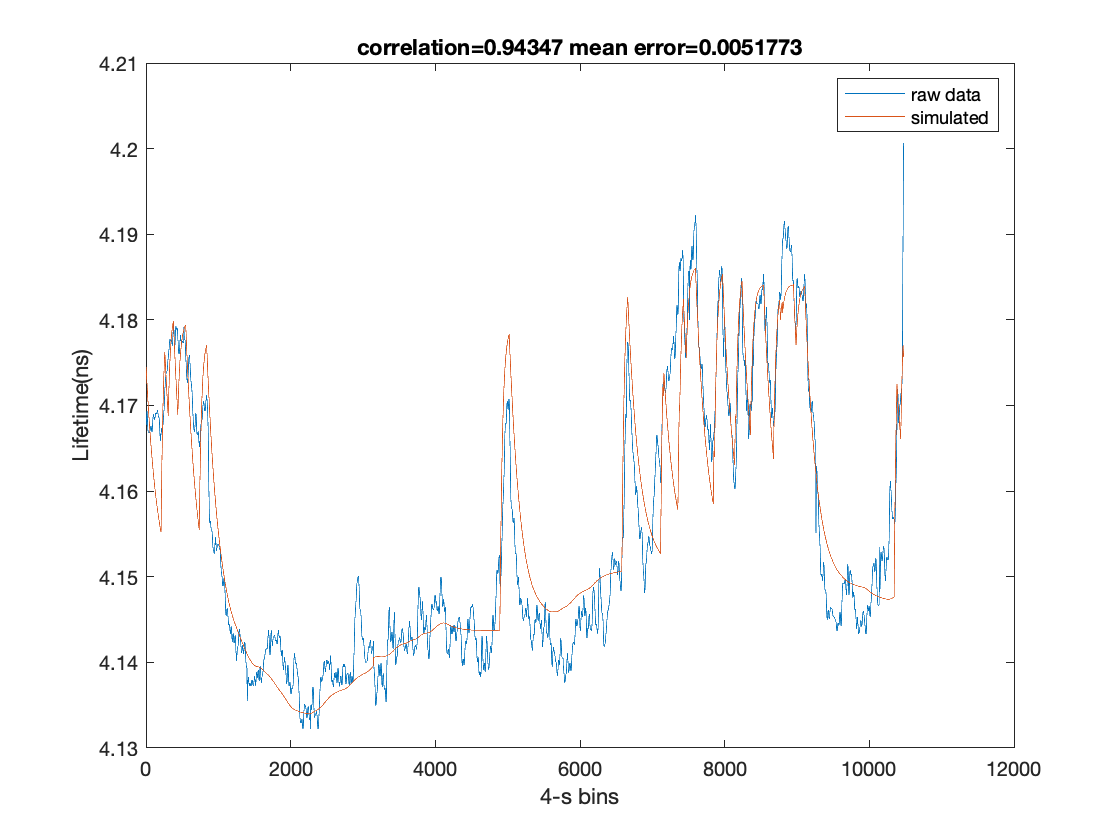

plot_length=length(rawT)/8;
figure
plot(rawT(end-plot_length+1:end))
hold on
plot(simulatedT(end-plot_length+1:end))
xlabel('4-s bins')
ylabel('Lifetime(ns)')
legend('raw data', 'simulated')
title(['correlation=',num2str(correlation),' mean error=',num2str(mean_error)])
saveas(gcf,[Temperature_path,ExperimentName,'.fig'])
saveas(gcf,[Temperature_path,ExperimentName,'.png'])

c=parcluster

c = 

 Local Cluster

    Properties: 

                   Profile: local
                  Modified: false
                      Host: pingchuans-imac
                NumWorkers: 25
                NumThreads: 4

        JobStorageLocation: /Users/pingchuanma/Library/Application Support/MathWorks/MATLAB/local_cluster_jobs/R2021b
   RequiresOnlineLicensing: false

    

j=batch(@example2_Optimization,1,{rawData, OptResults})

j = 

 Job

    Properties: 

                   ID: 49
                 Type: independent
             Username: pingchuanma
                State: running
       SubmitDateTime: 29-Aug-2022 16:46:29
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 4

      AutoAttachFiles: true
  Auto Attached Files: 

cd('/Volumes/PcSSDA/20220206_112_8_AChMut_SW_001')
ExperimentName='20220206_112_8_AChMut_SW_001'; % Give a specific name to this experiment or this analysis
FirstAcq=7; % What's the acquisition number of the first offical recording
number_of_acq = 12; % How many chunks of recordings are there?
Dark_hours=[7 8 9 10 11 12 13 14 15 16 17 18]

Dark_hours =      7     8     9    10    11    12    13    14    15    16    17    18


darktime_calc = 0; % 0 or 1, determining different method to calculate dark time
animal='112 AChmut 2 ';

analysis_name=[ExperimentName,'_analysis_'];
timebin=1;
ch=1;
FLPfiles='continuous aquistion data_'; 

Loading wave object  ...


Loading wave object  ...


Loading wave object  ...


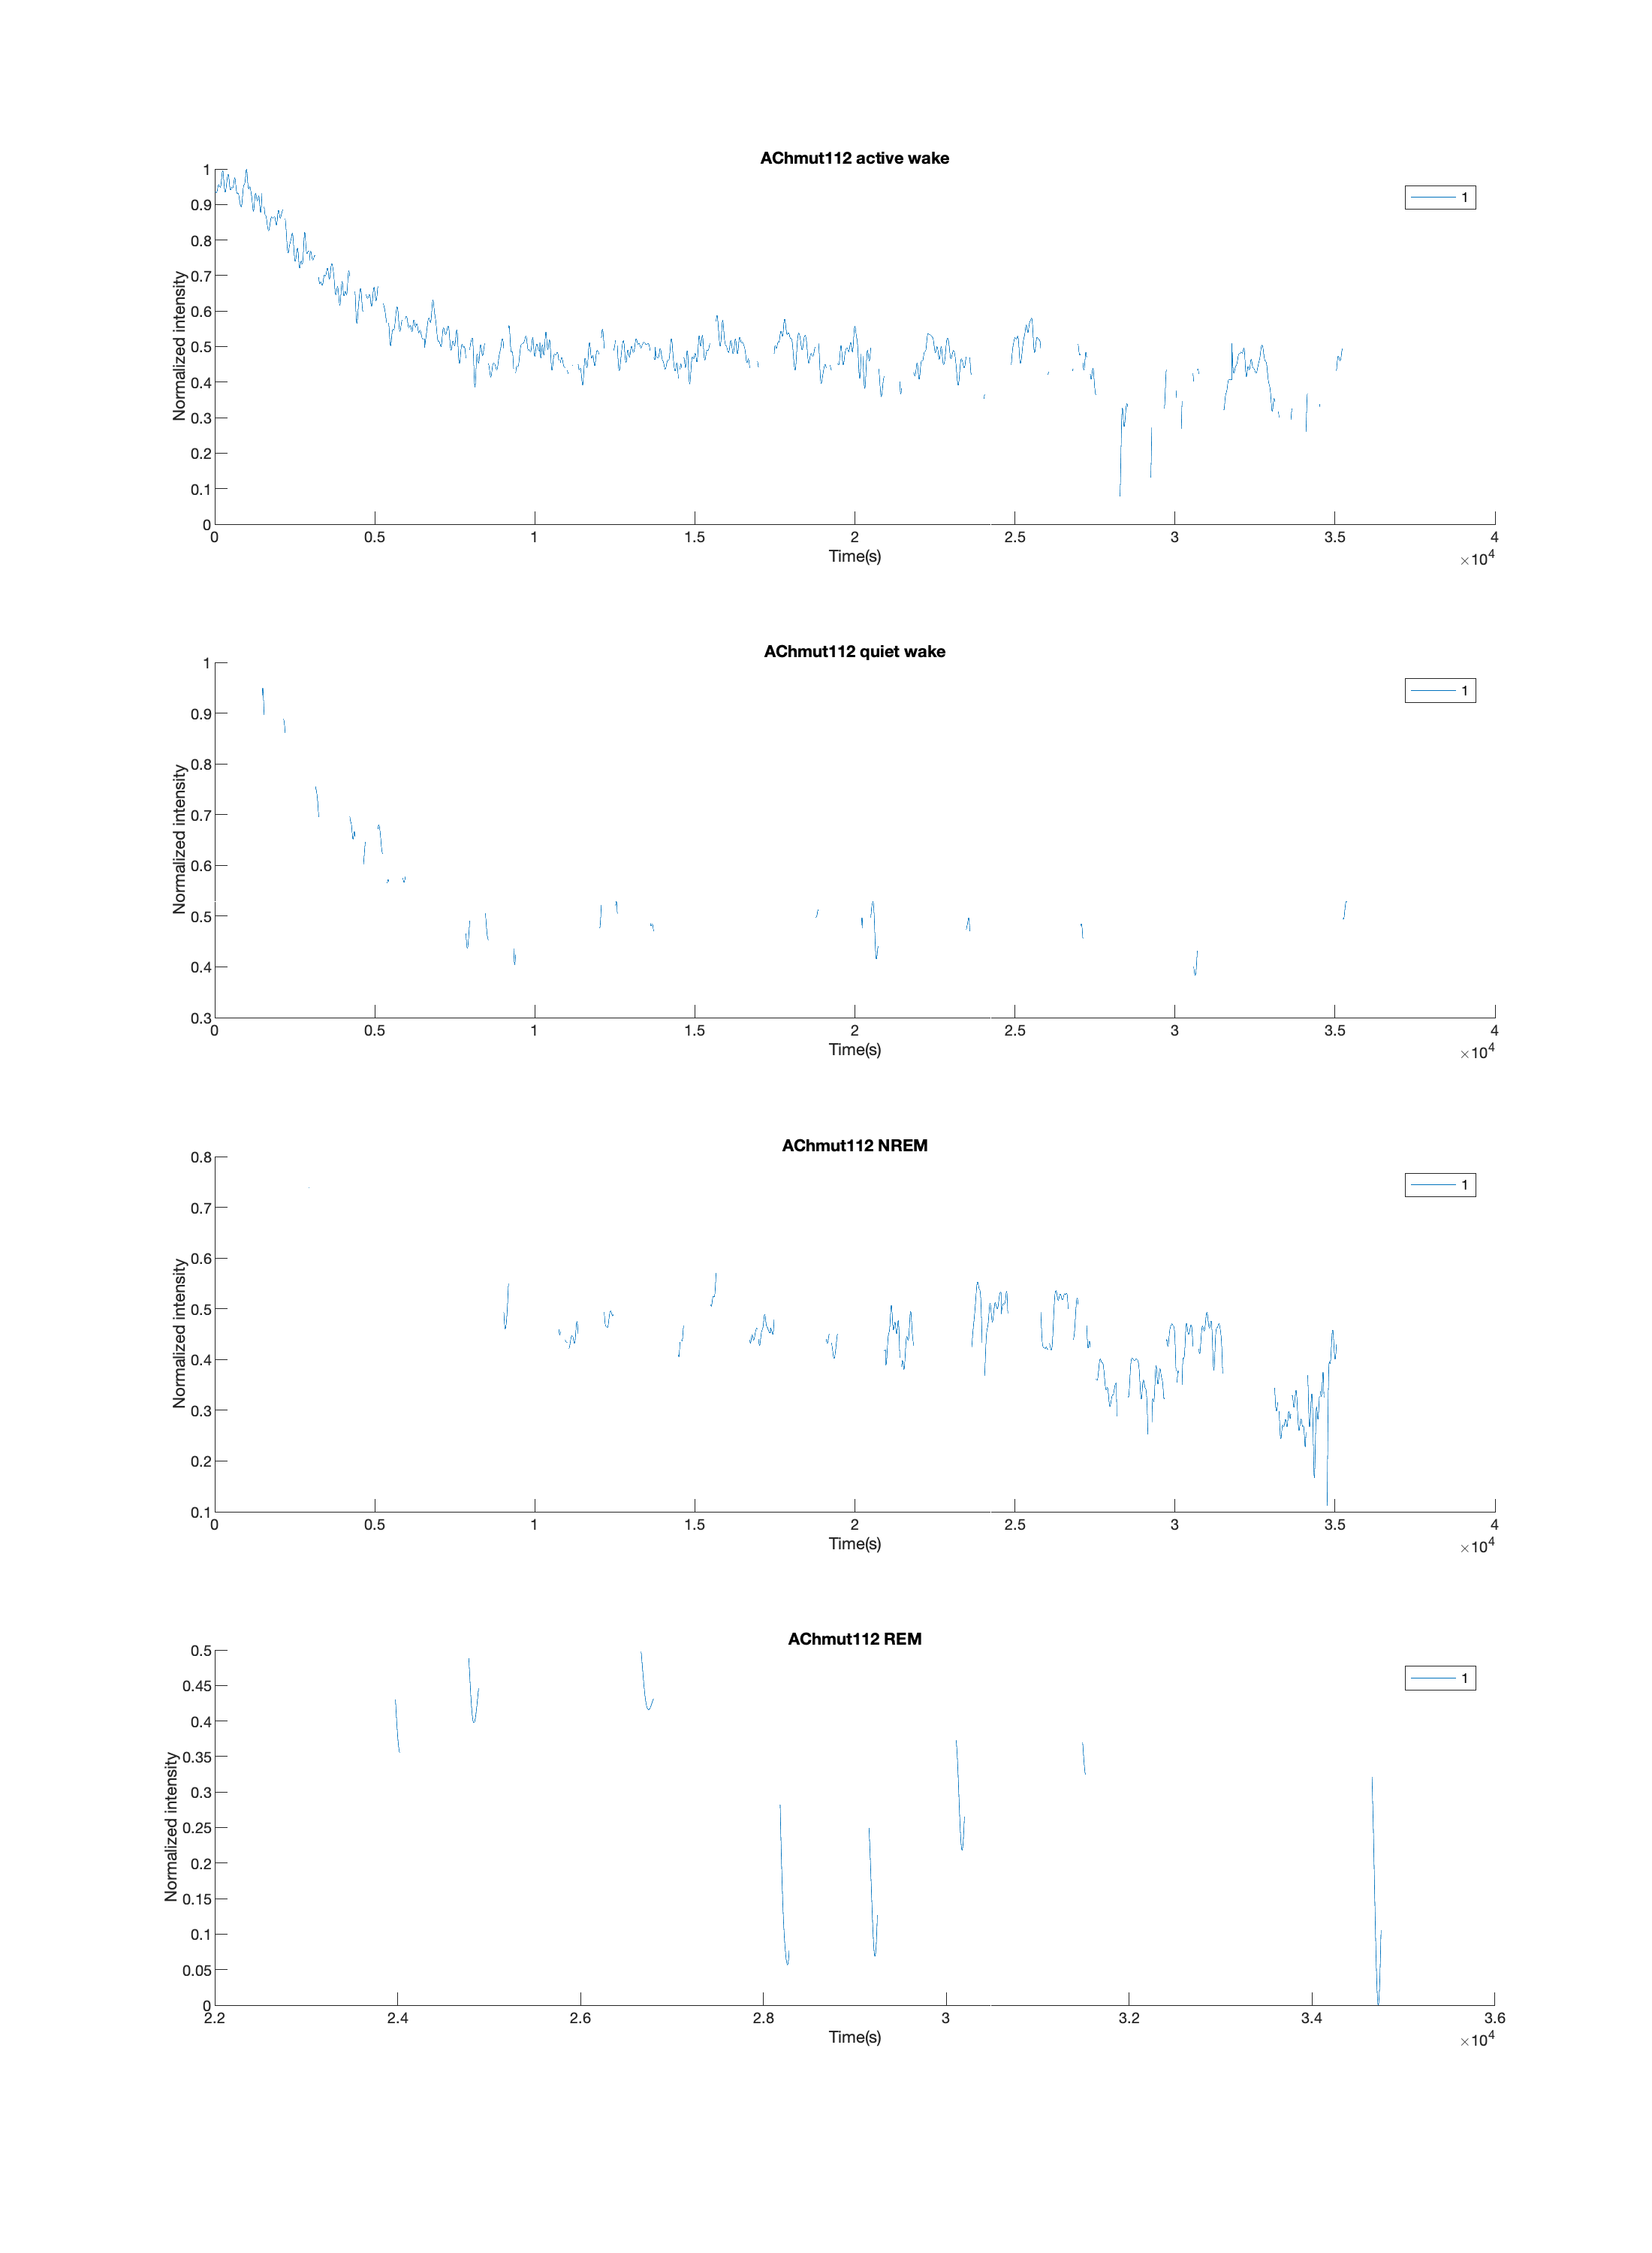

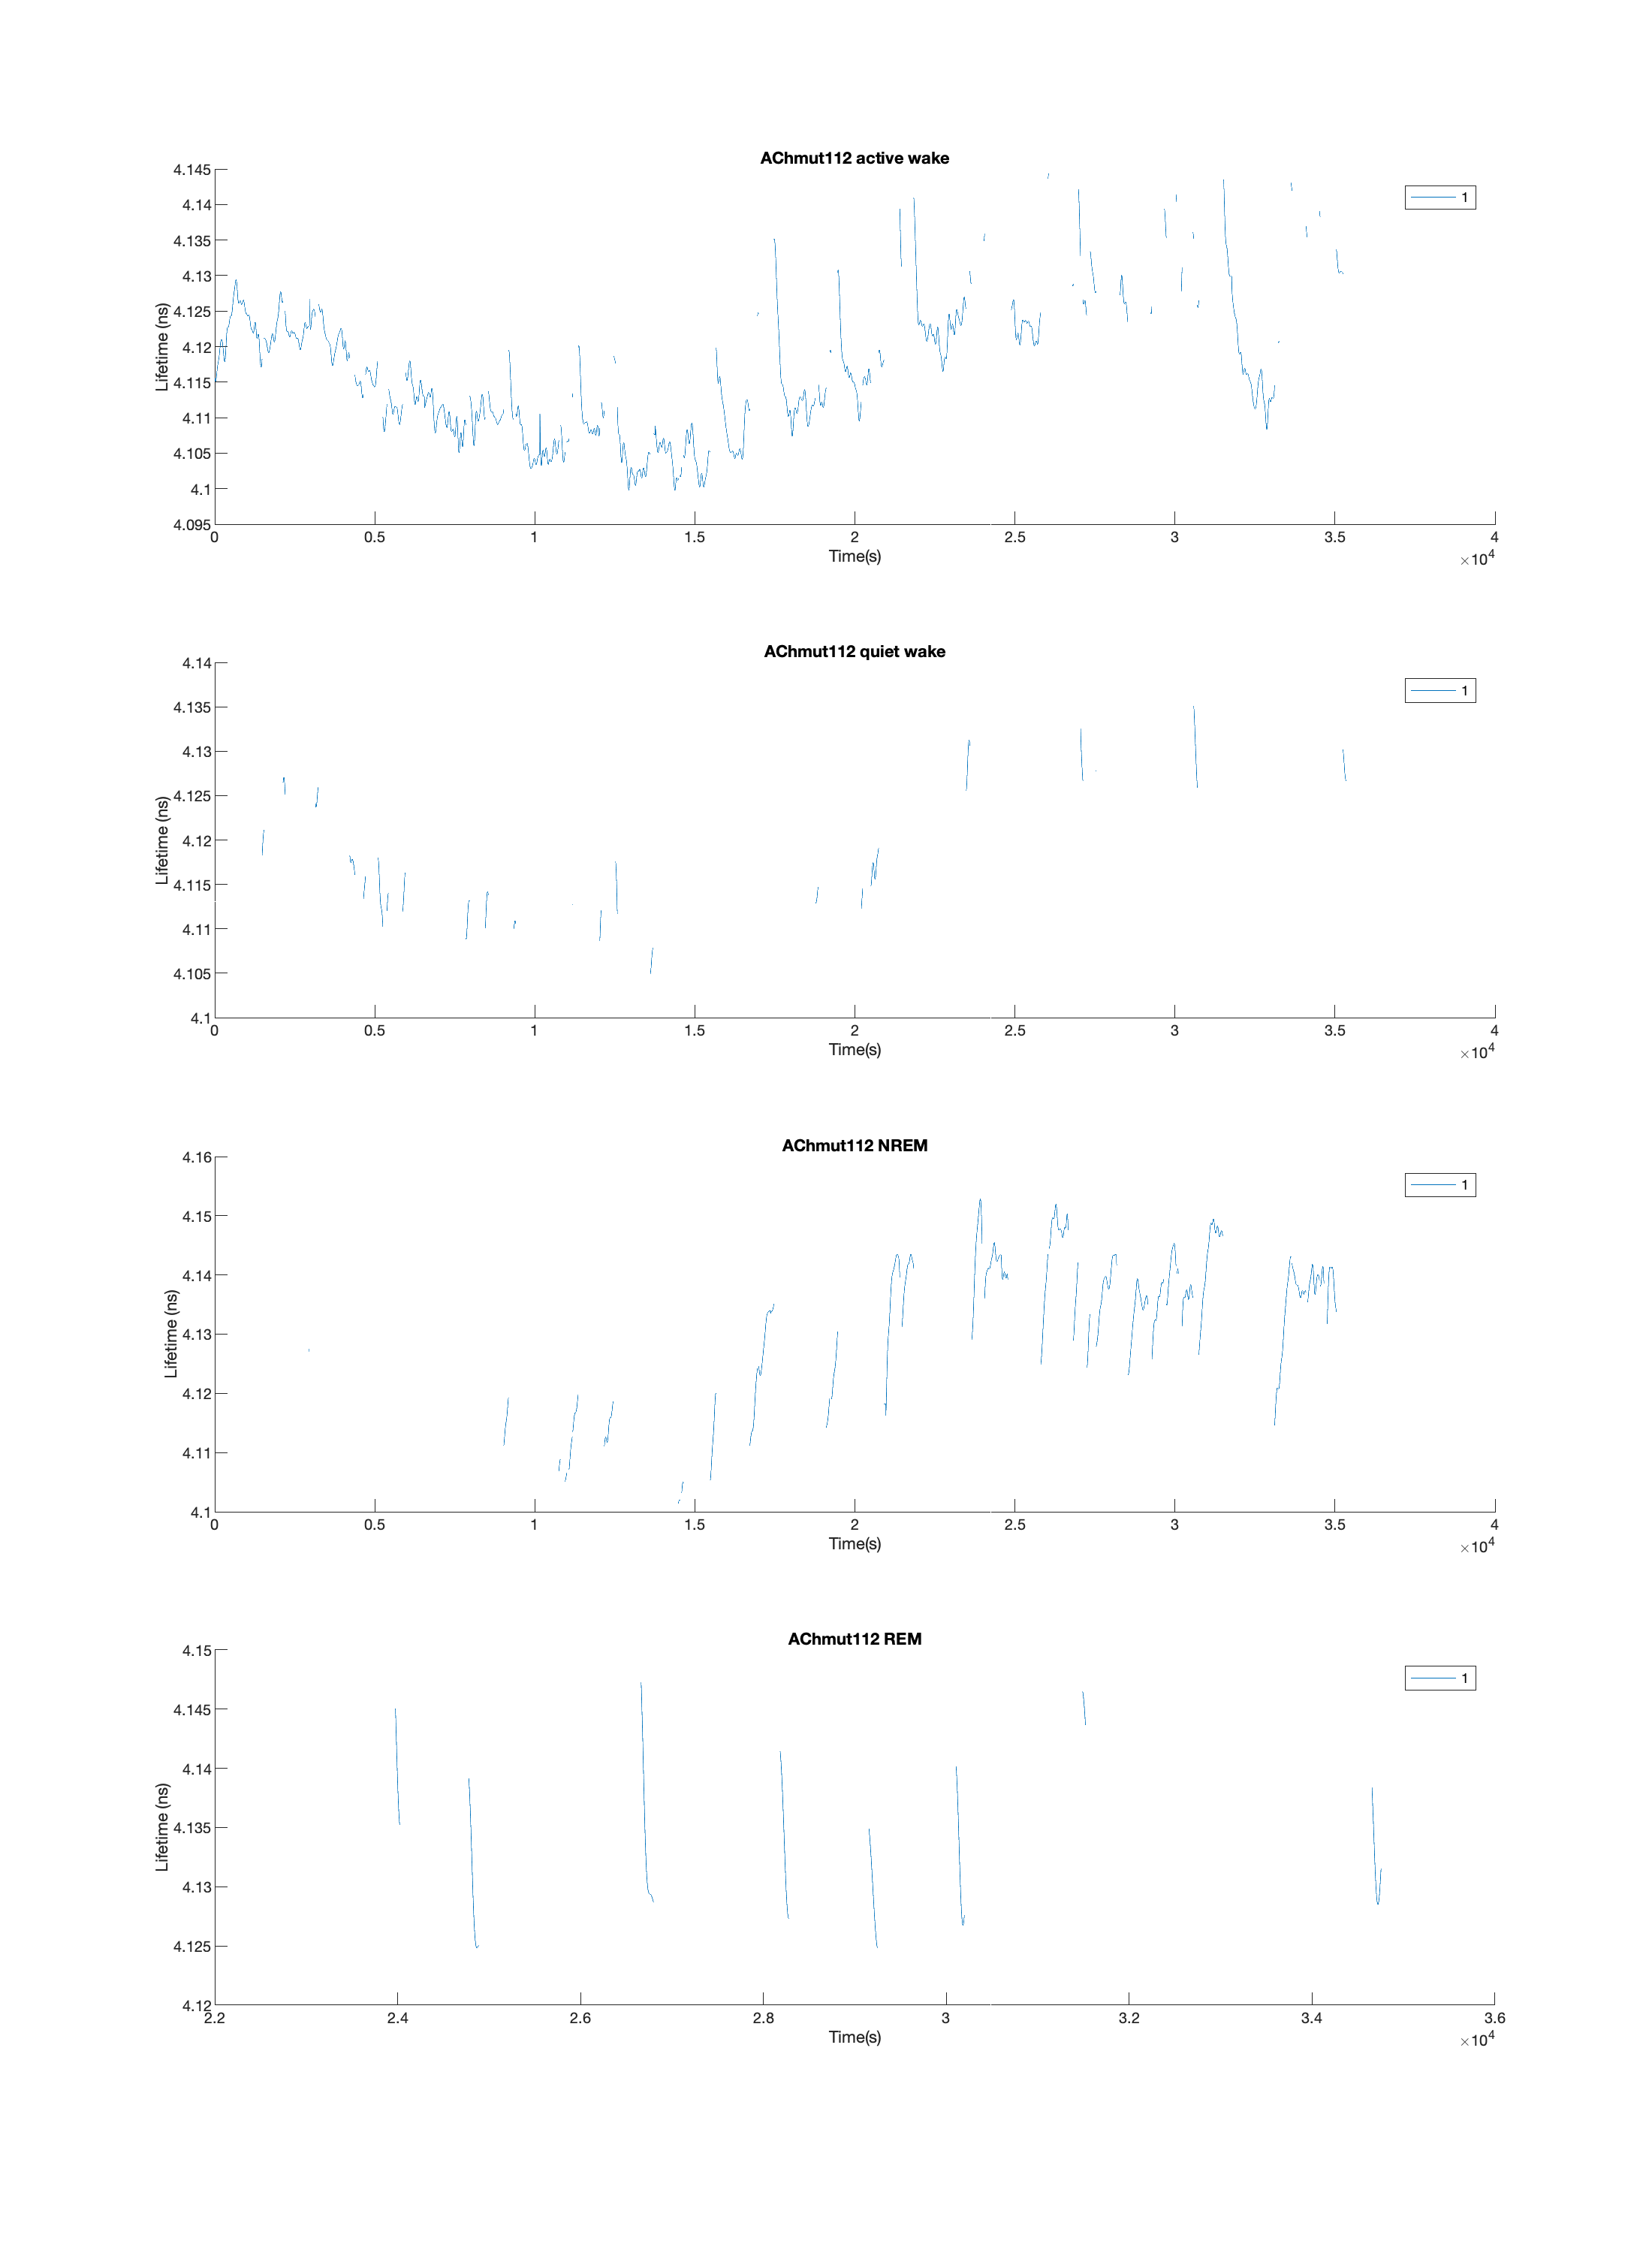

load('FLP_analysis.mat');

length(tau_empTrunc_all_darkonly)

ans =        41436


length(intensity_all_darkonly)

ans =        41436


tau_empTrunc_pooled=zeros(ceil(length(intensity_all_darkonly)/4),1);
time_pooled=zeros(ceil(length(intensity_all_darkonly)/4),1);
states_pooled=zeros(ceil(length(intensity_all_darkonly)/4),1);

for i=1:ceil(length(intensity_all_darkonly)/4)
    if (i-1)*4+4 > length(tau_empTrunc_all_darkonly)
        tau=tau_empTrunc_all_darkonly((i-1)*4+1:end);
        intensity=intensity_all_darkonly((i-1)*4+1:end);
    else
        tau=tau_empTrunc_all_darkonly((i-1)*4+1:(i-1)*4+4);
        intensity=intensity_all_darkonly((i-1)*4+1:(i-1)*4+4);
    end
    tau_empTrunc_pooled(i)=sum(tau.*intensity)/sum(intensity);
    time_pooled(i)=time_z_all_darkonly((i-1)*4+1);
    states_pooled(i)=states_for_time_all_dark((i-1)*4+1);
end

figure
yyaxis left
plot(time_pooled,tau_empTrunc_pooled)
yyaxis right
plot(time_pooled,states_pooled)

states_pooled(find(states_pooled==2))=0;
states_pooled(find(states_pooled==3))=1;
states_pooled(find(states_pooled==4))=1;

figure
yyaxis left
plot(time_pooled,tau_empTrunc_pooled)
yyaxis right
plot(time_pooled,states_pooled)

Temperature_path='/Users/pingchuanma/Desktop/ChenLab_Data/Lifetime_temperature/'

Temperature_path = '/Users/pingchuanma/Desktop/ChenLab_Data/Lifetime_temperature/'

rawData=([Temperature_path,ExperimentName,'.mat'])

rawData = '/Users/pingchuanma/Desktop/ChenLab_Data/Lifetime_temperature/20220206_112_8_AChMut_SW_001.mat'

OptResults=([Temperature_path,ExperimentName,'OptResults.mat'])

OptResults = '/Users/pingchuanma/Desktop/ChenLab_Data/Lifetime_temperature/20220206_112_8_AChMut_SW_001OptResults.mat'

save(rawData,'time_pooled','tau_empTrunc_pooled','states_pooled')

load(OptResults)

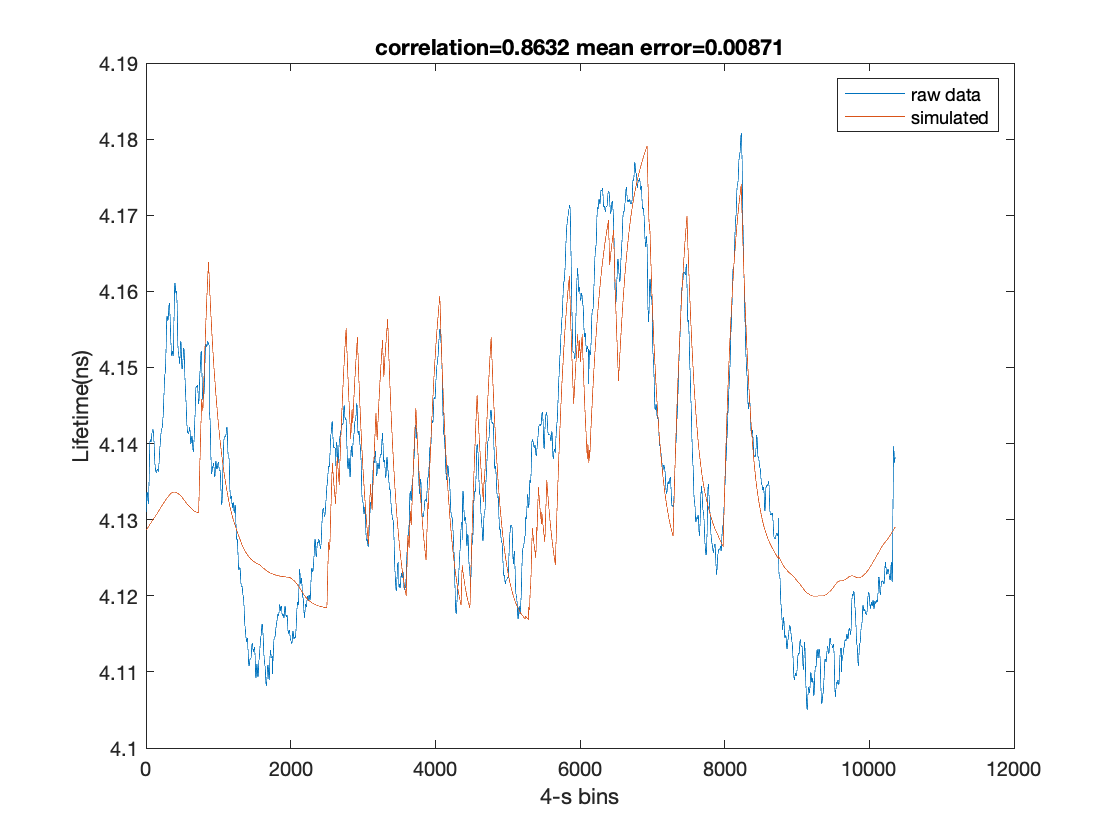

plot_length=length(rawT)/8;
figure
plot(rawT(end-plot_length+1:end))
hold on
plot(simulatedT(end-plot_length+1:end))
xlabel('4-s bins')
ylabel('Lifetime(ns)')
legend('raw data', 'simulated')
title(['correlation=',num2str(correlation),' mean error=',num2str(mean_error)])
saveas(gcf,[Temperature_path,ExperimentName,'.fig'])
saveas(gcf,[Temperature_path,ExperimentName,'.png'])

j=batch(@example2_Optimization,1,{rawData, OptResults})

j = 

 Job

    Properties: 

                   ID: 50
                 Type: independent
             Username: pingchuanma
                State: running
       SubmitDateTime: 29-Aug-2022 16:51:16
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 4

      AutoAttachFiles: true
  Auto Attached Files: 

cd('/Volumes/PcSSDA/20220425_109_AChmut_SW_001')
ExperimentName='20220425_109_AChmut_SW_001'; % Give a specific name to this experiment or this analysis
FirstAcq=11; % What's the acquisition number of the first offical recording
number_of_acq = 24; % How many chunks of recordings are there?
Dark_hours=[12 13 14 15 16 17 18 19 20 21 22 23]

Dark_hours =     12    13    14    15    16    17    18    19    20    21    22    23


darktime_calc = 0; % 0 or 1, determining different method to calculate dark time
animal='109 AChmut 1 ';

analysis_name=[ExperimentName,'_analysis_'];
timebin=1;
ch=1;
FLPfiles='continuous aquistion data_'; 

Loading wave object  ...


Loading wave object  ...


Loading wave object  ...


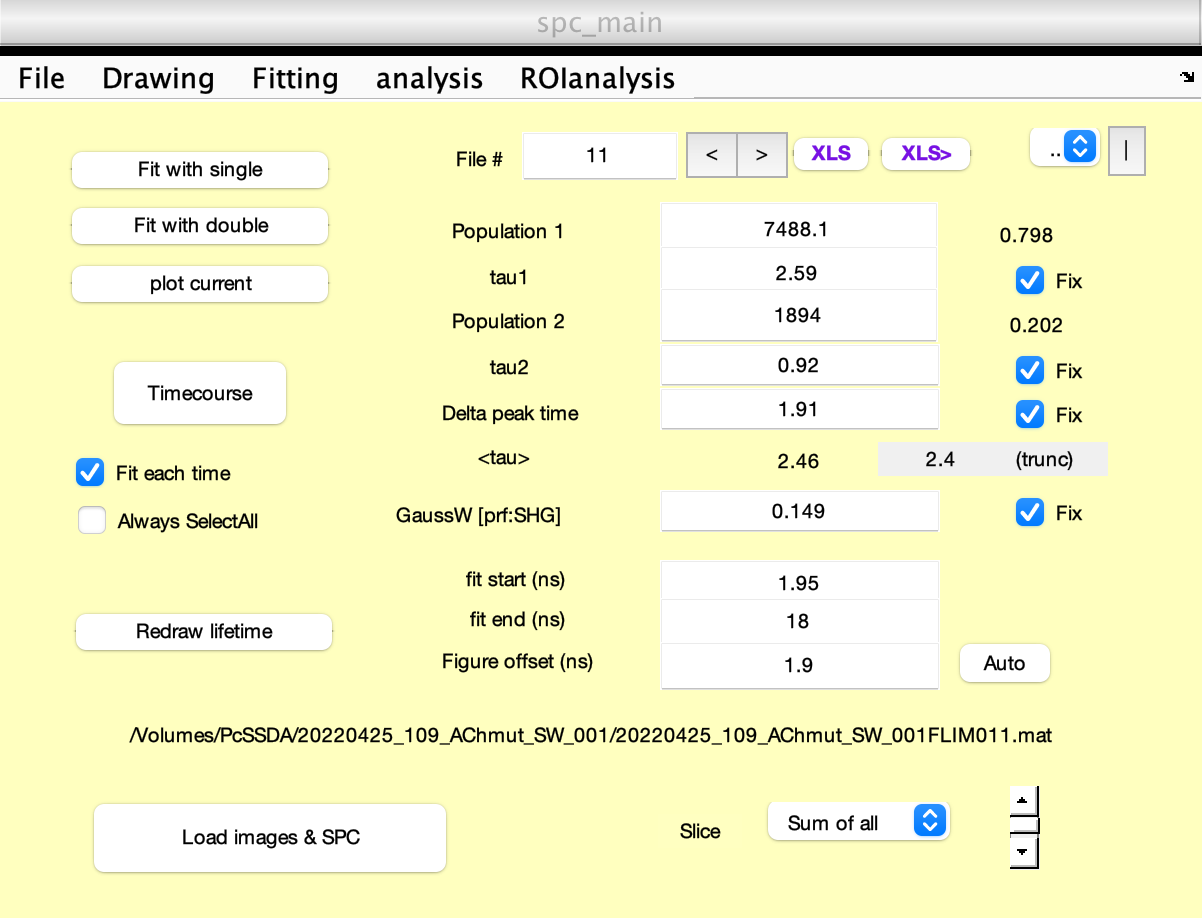

load('FLP_analysis.mat');

length(tau_empTrunc_all_darkonly)

ans =        41268


length(intensity_all_darkonly)

ans =        41268


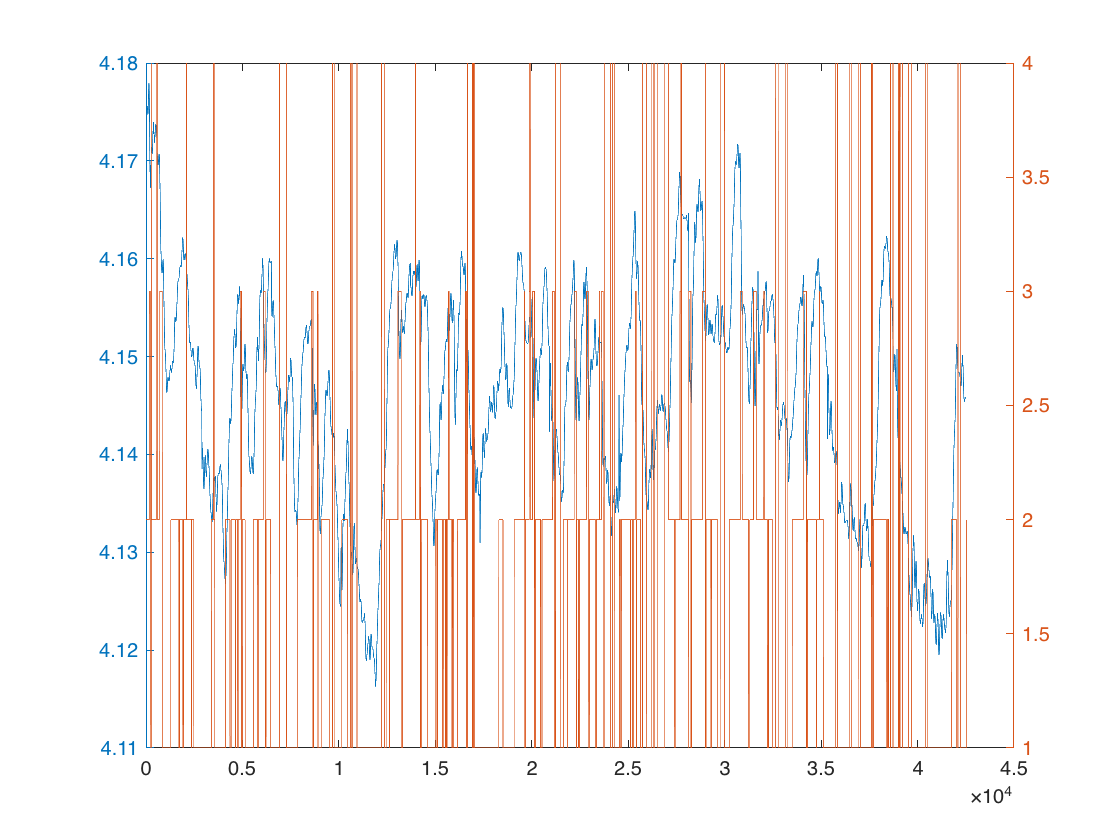

tau_empTrunc_pooled=zeros(ceil(length(intensity_all_darkonly)/4),1);
time_pooled=zeros(ceil(length(intensity_all_darkonly)/4),1);
states_pooled=zeros(ceil(length(intensity_all_darkonly)/4),1);

for i=1:ceil(length(intensity_all_darkonly)/4)
    if (i-1)*4+4 > length(tau_empTrunc_all_darkonly)
        tau=tau_empTrunc_all_darkonly((i-1)*4+1:end);
        intensity=intensity_all_darkonly((i-1)*4+1:end);
    else
        tau=tau_empTrunc_all_darkonly((i-1)*4+1:(i-1)*4+4);
        intensity=intensity_all_darkonly((i-1)*4+1:(i-1)*4+4);
    end
    tau_empTrunc_pooled(i)=sum(tau.*intensity)/sum(intensity);
    time_pooled(i)=time_z_all_darkonly((i-1)*4+1);
    states_pooled(i)=states_for_time_all_dark((i-1)*4+1);
end

figure
yyaxis left
plot(time_pooled,tau_empTrunc_pooled)
yyaxis right
plot(time_pooled,states_pooled)

states_pooled(find(states_pooled==2))=0;
states_pooled(find(states_pooled==3))=1;
states_pooled(find(states_pooled==4))=1;

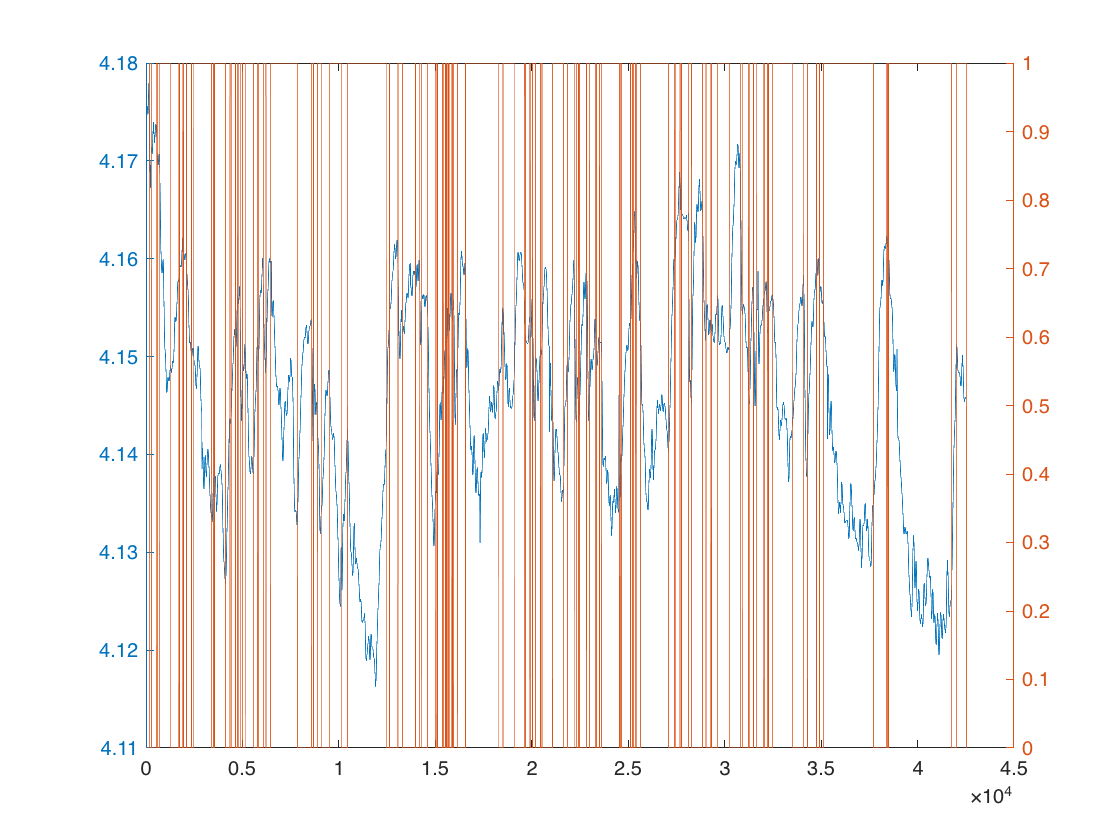

figure
yyaxis left
plot(time_pooled,tau_empTrunc_pooled)
yyaxis right
plot(time_pooled,states_pooled)

Temperature_path='/Users/pingchuanma/Desktop/ChenLab_Data/Lifetime_temperature/'

Temperature_path = '/Users/pingchuanma/Desktop/ChenLab_Data/Lifetime_temperature/'

rawData=([Temperature_path,ExperimentName,'.mat'])

rawData = '/Users/pingchuanma/Desktop/ChenLab_Data/Lifetime_temperature/20220425_109_AChmut_SW_001.mat'

OptResults=([Temperature_path,ExperimentName,'OptResults.mat'])

OptResults = '/Users/pingchuanma/Desktop/ChenLab_Data/Lifetime_temperature/20220425_109_AChmut_SW_001OptResults.mat'

save(rawData,'time_pooled','tau_empTrunc_pooled','states_pooled')

load(OptResults)

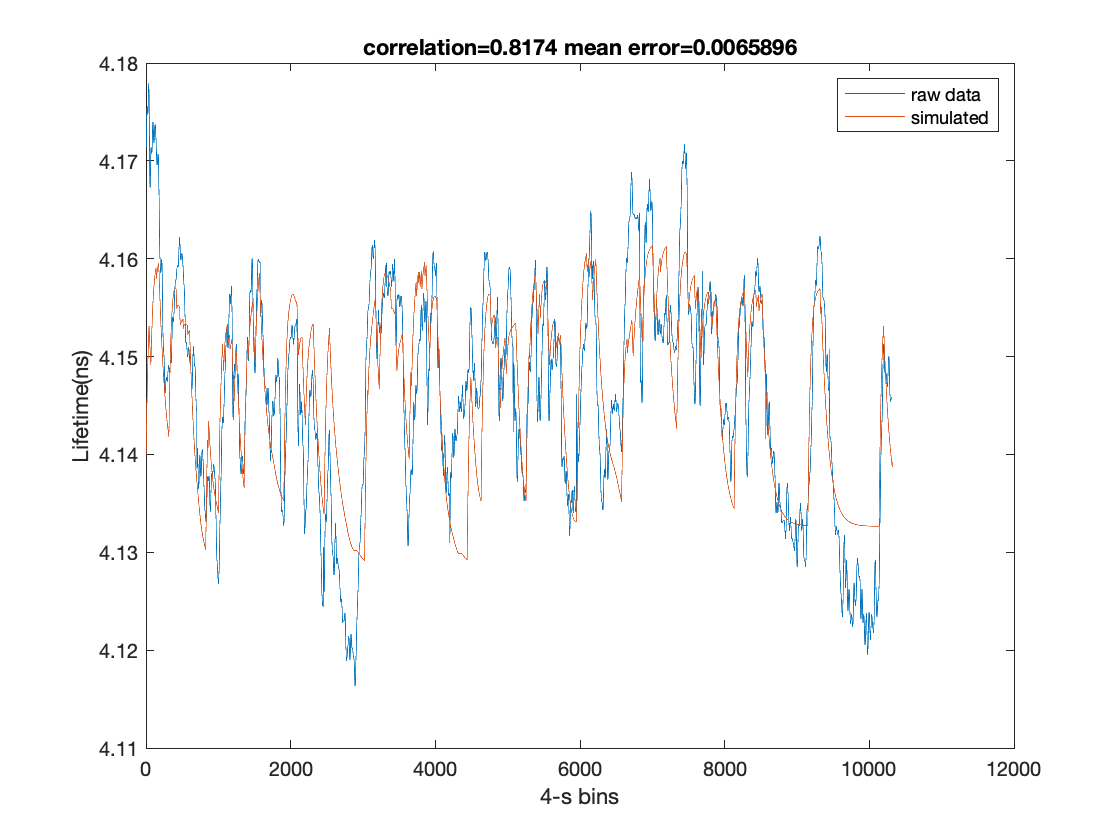

plot_length=length(rawT)/8;
figure
plot(rawT(end-plot_length+1:end))
hold on
plot(simulatedT(end-plot_length+1:end))
xlabel('4-s bins')
ylabel('Lifetime(ns)')
legend('raw data', 'simulated')
title(['correlation=',num2str(correlation),' mean error=',num2str(mean_error)])
saveas(gcf,[Temperature_path,ExperimentName,'.fig'])
saveas(gcf,[Temperature_path,ExperimentName,'.png'])

j=batch(@example2_Optimization,1,{rawData, OptResults})

j = 

 Job

    Properties: 

                   ID: 51
                 Type: independent
             Username: pingchuanma
                State: running
       SubmitDateTime: 29-Aug-2022 16:52:34
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 4

      AutoAttachFiles: true
  Auto Attached Files: 

cd('/Volumes/PcSSDA/20220207_109_AChMut_SW_001')
ExperimentName='20220207_109_AChMut_SW_001'; % Give a specific name to this experiment or this analysis
FirstAcq=10; % What's the acquisition number of the first offical recording
number_of_acq = 10; % How many chunks of recordings are there?
Dark_hours=[10 11 12 13 14 15 16 17 18 19 20 21 22]

Dark_hours =     10    11    12    13    14    15    16    17    18    19    20    21    22


darktime_calc = 0; % 0 or 1, determining different method to calculate dark time
animal='109 AChmut 2 ';

analysis_name=[ExperimentName,'_analysis_'];
timebin=1;
ch=1;
FLPfiles='continuous aquistion data_'; 

Loading wave object  ...


Loading wave object  ...


Loading wave object  ...


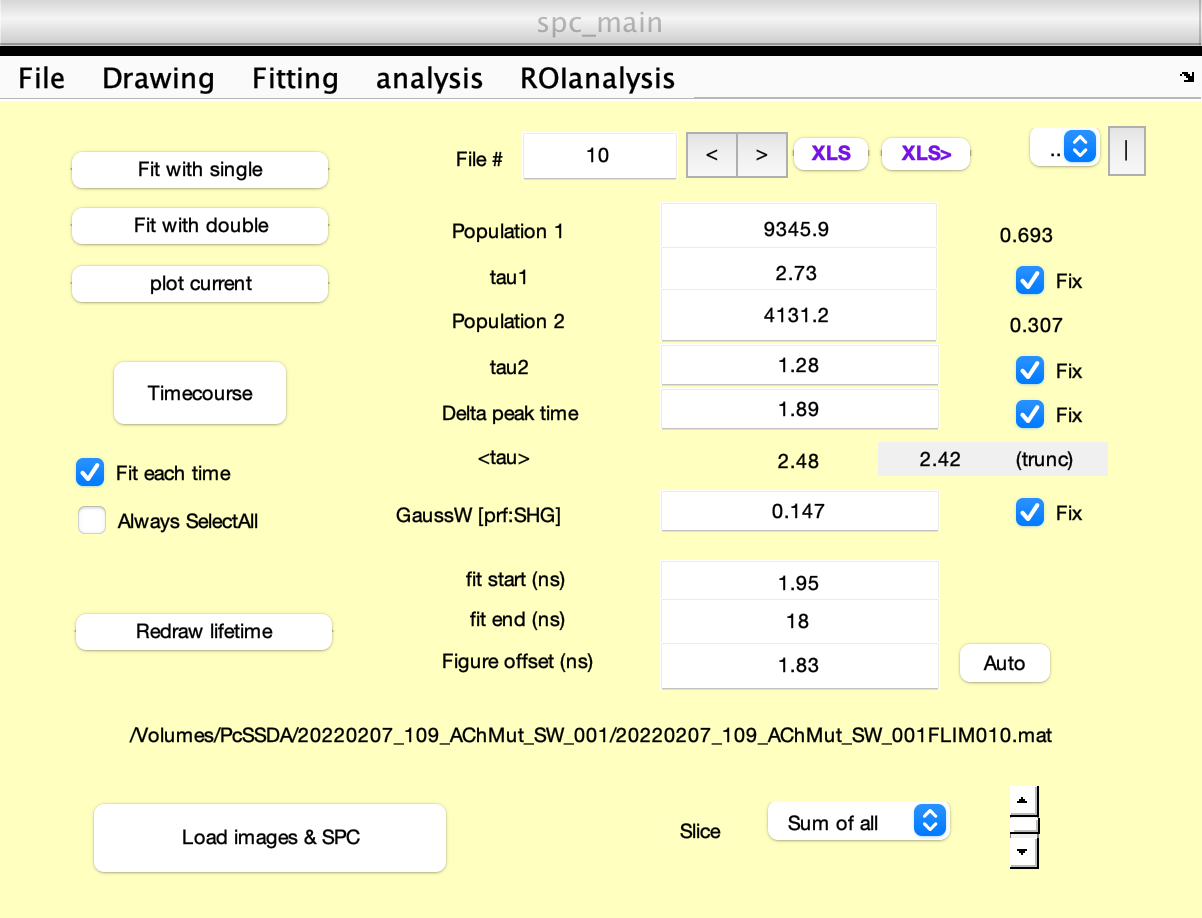

load('FLP_analysis.mat');

length(tau_empTrunc_all_darkonly)

ans =        34329


length(intensity_all_darkonly)

ans =        34329


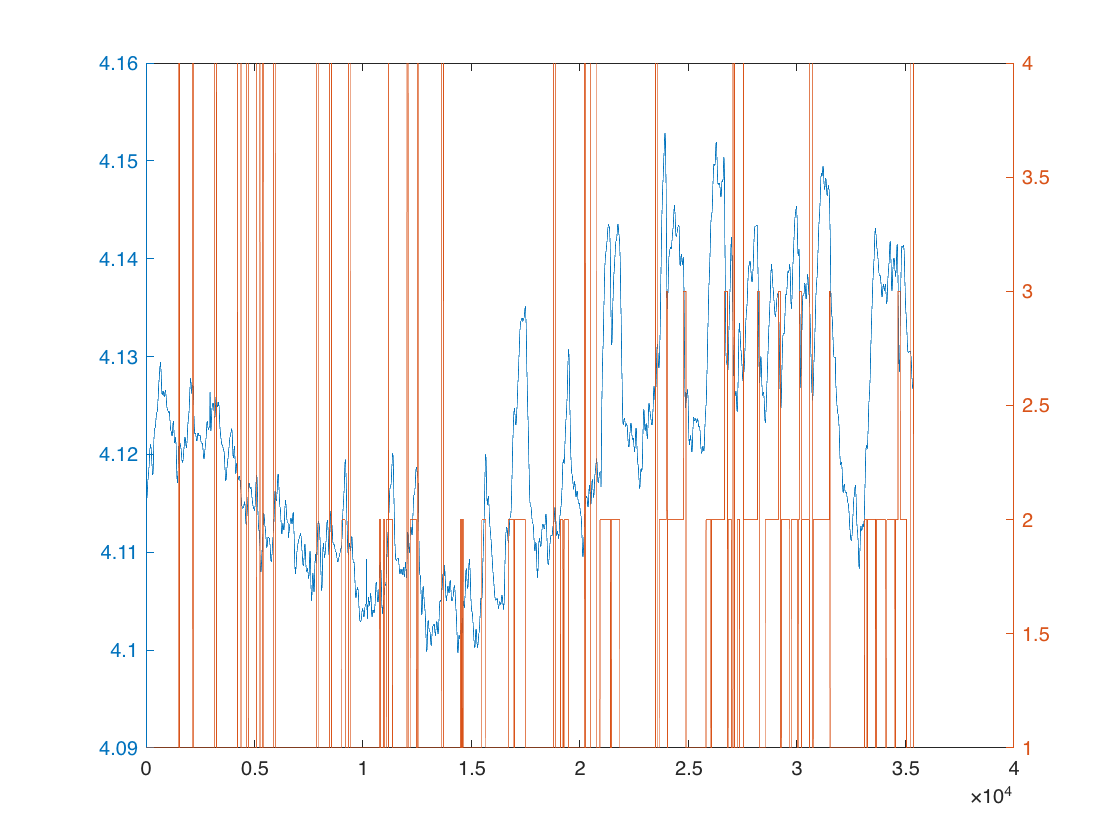

tau_empTrunc_pooled=zeros(ceil(length(intensity_all_darkonly)/4),1);
time_pooled=zeros(ceil(length(intensity_all_darkonly)/4),1);
states_pooled=zeros(ceil(length(intensity_all_darkonly)/4),1);

for i=1:ceil(length(intensity_all_darkonly)/4)
    if (i-1)*4+4 > length(tau_empTrunc_all_darkonly)
        tau=tau_empTrunc_all_darkonly((i-1)*4+1:end);
        intensity=intensity_all_darkonly((i-1)*4+1:end);
    else
        tau=tau_empTrunc_all_darkonly((i-1)*4+1:(i-1)*4+4);
        intensity=intensity_all_darkonly((i-1)*4+1:(i-1)*4+4);
    end
    tau_empTrunc_pooled(i)=sum(tau.*intensity)/sum(intensity);
    time_pooled(i)=time_z_all_darkonly((i-1)*4+1);
    states_pooled(i)=states_for_time_all_dark((i-1)*4+1);
end

figure
yyaxis left
plot(time_pooled,tau_empTrunc_pooled)
yyaxis right
plot(time_pooled,states_pooled)

states_pooled(find(states_pooled==2))=0;
states_pooled(find(states_pooled==3))=1;
states_pooled(find(states_pooled==4))=1;

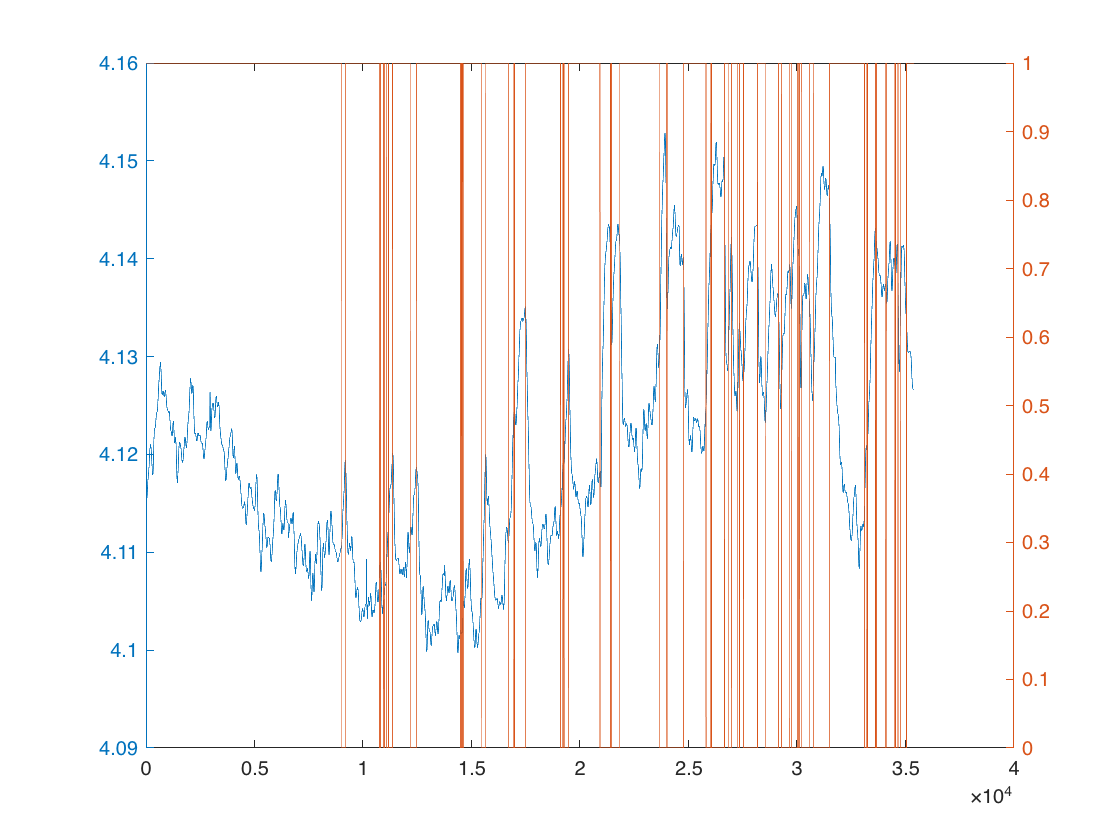

figure
yyaxis left
plot(time_pooled,tau_empTrunc_pooled)
yyaxis right
plot(time_pooled,states_pooled)

Temperature_path='/Users/pingchuanma/Desktop/ChenLab_Data/Lifetime_temperature/'

Temperature_path = '/Users/pingchuanma/Desktop/ChenLab_Data/Lifetime_temperature/'

rawData=([Temperature_path,ExperimentName,'.mat'])

rawData = '/Users/pingchuanma/Desktop/ChenLab_Data/Lifetime_temperature/20220207_109_AChMut_SW_001.mat'

OptResults=([Temperature_path,ExperimentName,'OptResults.mat'])

OptResults = '/Users/pingchuanma/Desktop/ChenLab_Data/Lifetime_temperature/20220207_109_AChMut_SW_001OptResults.mat'

save(rawData,'time_pooled','tau_empTrunc_pooled','states_pooled')

load(OptResults)

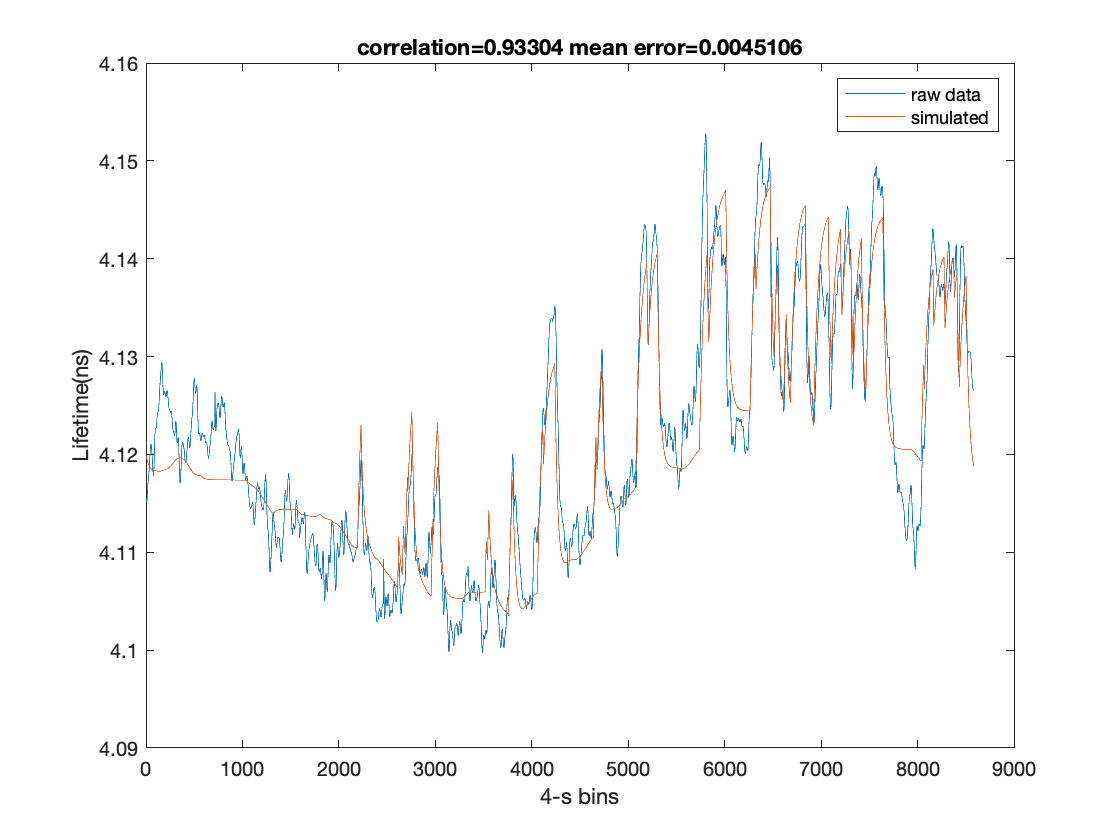

plot_length=length(rawT)/8;
figure
plot(rawT(end-plot_length+1:end))
hold on
plot(simulatedT(end-plot_length+1:end))
xlabel('4-s bins')
ylabel('Lifetime(ns)')
legend('raw data', 'simulated')
title(['correlation=',num2str(correlation),' mean error=',num2str(mean_error)])
saveas(gcf,[Temperature_path,ExperimentName,'.fig'])
saveas(gcf,[Temperature_path,ExperimentName,'.png'])

j=batch(@example2_Optimization,1,{rawData, OptResults})

j = 

 Job

    Properties: 

                   ID: 52
                 Type: independent
             Username: pingchuanma
                State: running
       SubmitDateTime: 29-Aug-2022 16:53:59
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 4

      AutoAttachFiles: true
  Auto Attached Files: 

cd('/Volumes/PcSSDA/AChMut/20220712_PM29_111_Achmut_001')
ExperimentName='20220712_PM29_111_Achmut_001'; % Give a specific name to this experiment or this analysis
FirstAcq=10; % What's the acquisition number of the first offical recording
number_of_acq = 24; % How many chunks of recordings are there?
Dark_hours=[17 18 19 20 21 22 23 24 25 26 27 28 29]

Dark_hours =     17    18    19    20    21    22    23    24    25    26    27    28    29


darktime_calc = 0; % 0 or 1, determining different method to calculate dark time

analysis_name=[ExperimentName,'_analysis_'];
timebin=1;
ch=1;
FLPfiles='continuous aquistion data_'; 

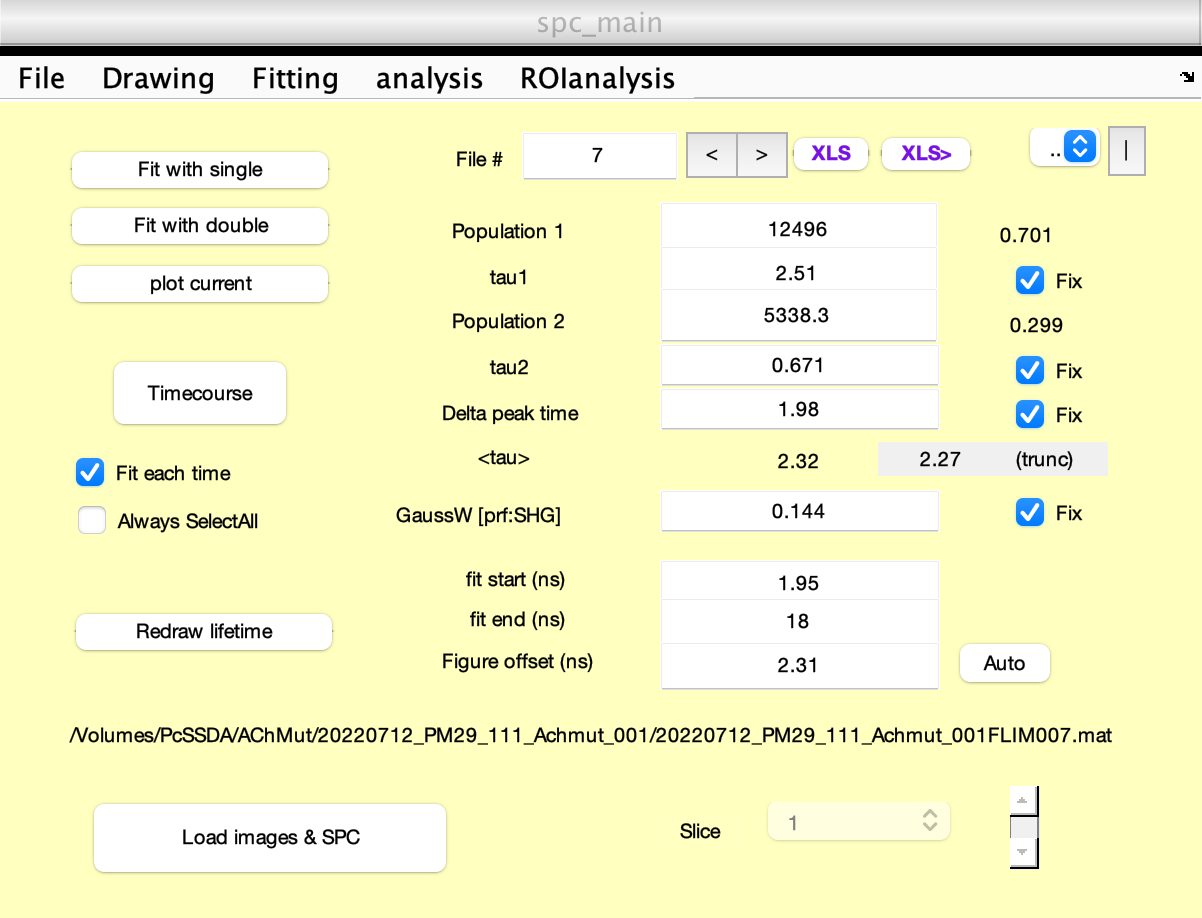

load('FLP_analysis.mat');

length(tau_empTrunc_all_darkonly)

ans =        41835


length(intensity_all_darkonly)

ans =        41835


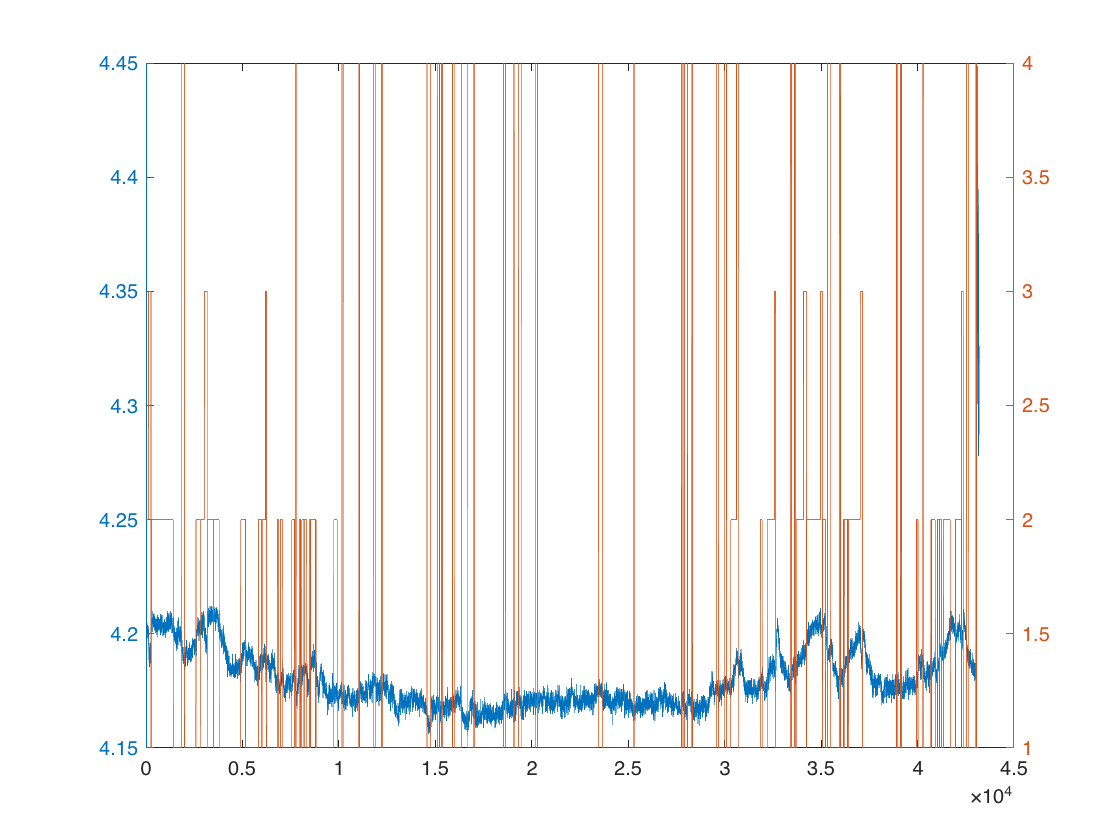

tau_empTrunc_pooled=zeros(ceil(length(intensity_all_darkonly)/4),1);
time_pooled=zeros(ceil(length(intensity_all_darkonly)/4),1);
states_pooled=zeros(ceil(length(intensity_all_darkonly)/4),1);

for i=1:ceil(length(intensity_all_darkonly)/4)
    if (i-1)*4+4 > length(tau_empTrunc_all_darkonly)
        tau=tau_empTrunc_all_darkonly((i-1)*4+1:end);
        intensity=intensity_all_darkonly((i-1)*4+1:end);
    else
        tau=tau_empTrunc_all_darkonly((i-1)*4+1:(i-1)*4+4);
        intensity=intensity_all_darkonly((i-1)*4+1:(i-1)*4+4);
    end
    tau_empTrunc_pooled(i)=sum(tau.*intensity)/sum(intensity);
    time_pooled(i)=time_z_all_darkonly((i-1)*4+1);
    states_pooled(i)=states_for_time_all_dark((i-1)*4+1);
end

figure
yyaxis left
plot(time_pooled,tau_empTrunc_pooled)
yyaxis right
plot(time_pooled,states_pooled)

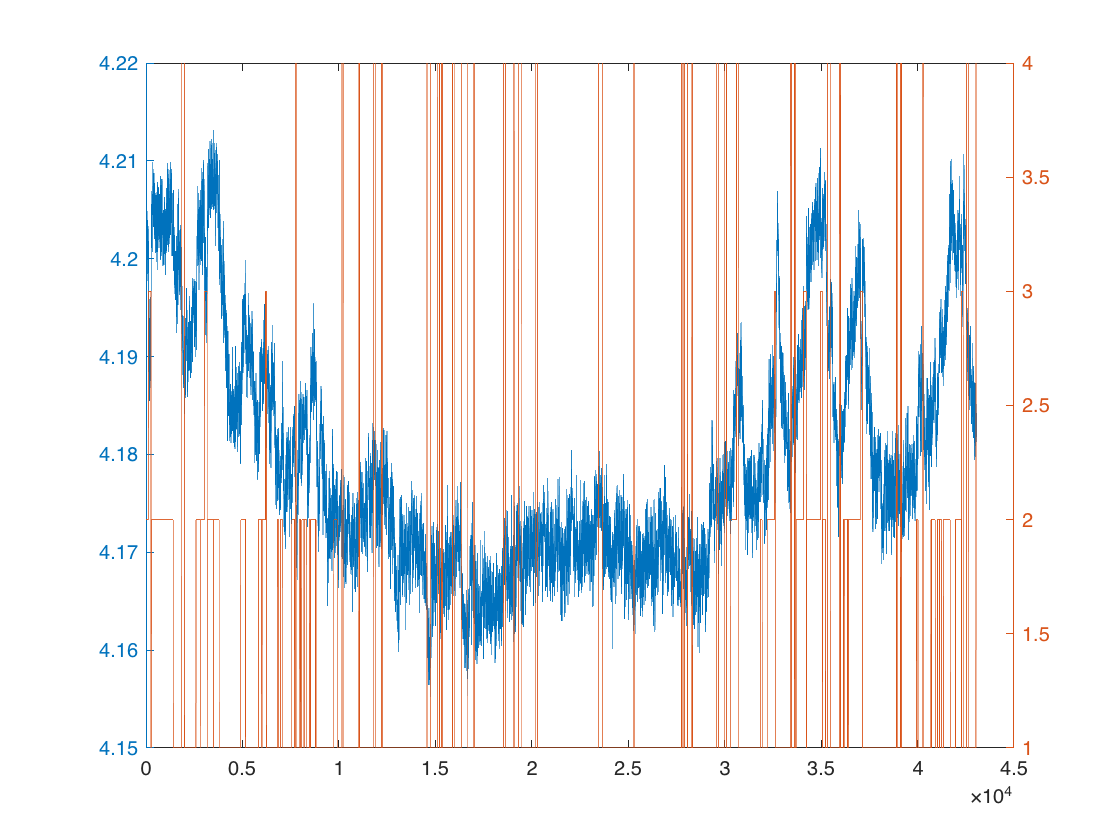

ignore_data=find(tau_empTrunc_pooled>4.25);
tau_empTrunc_pooled(ignore_data)=[];
time_pooled(ignore_data)=[];
states_pooled(ignore_data)=[];

figure
yyaxis left
plot(time_pooled,tau_empTrunc_pooled)
yyaxis right
plot(time_pooled,states_pooled)

states_pooled(find(states_pooled==2))=0;
states_pooled(find(states_pooled==3))=1;
states_pooled(find(states_pooled==4))=1;

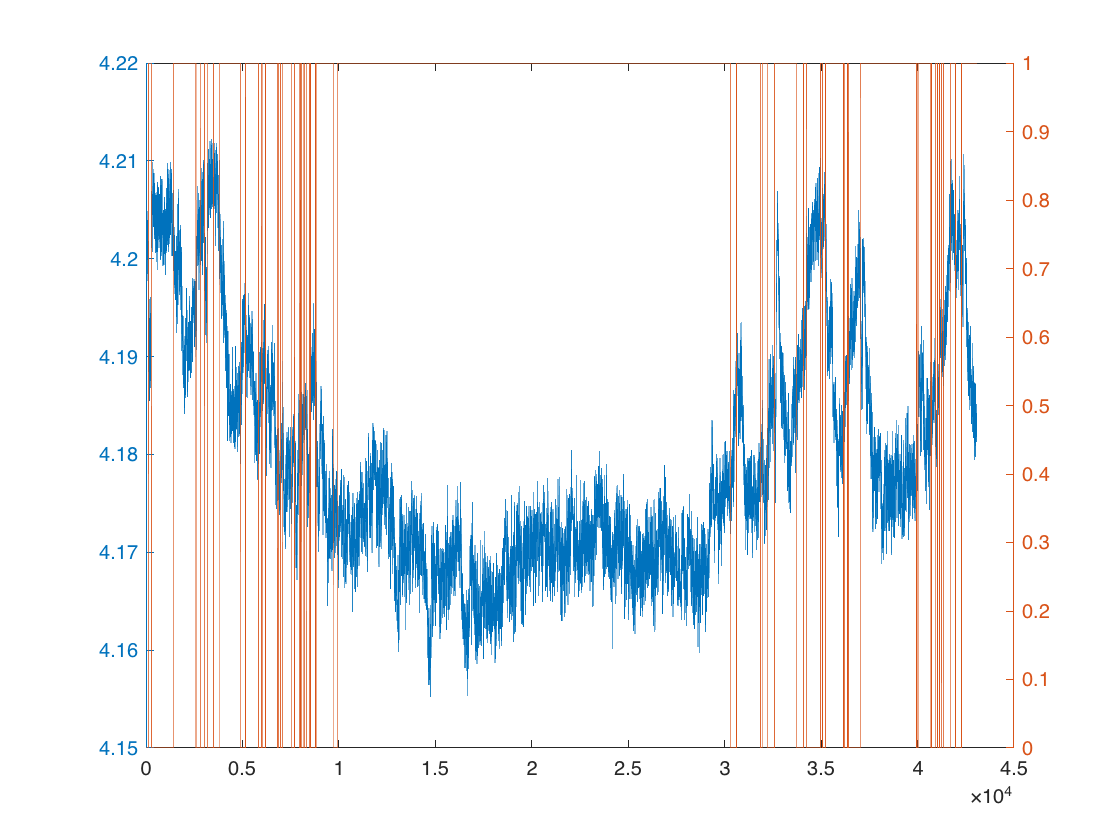

figure
yyaxis left
plot(time_pooled,tau_empTrunc_pooled)
yyaxis right
plot(time_pooled,states_pooled)

Temperature_path='/Users/pingchuanma/Desktop/ChenLab_Data/Lifetime_temperature/'

Temperature_path = '/Users/pingchuanma/Desktop/ChenLab_Data/Lifetime_temperature/'

rawData=([Temperature_path,ExperimentName,'.mat'])

rawData = '/Users/pingchuanma/Desktop/ChenLab_Data/Lifetime_temperature/20220712_PM29_111_Achmut_001.mat'

OptResults=([Temperature_path,ExperimentName,'OptResults.mat'])

OptResults = '/Users/pingchuanma/Desktop/ChenLab_Data/Lifetime_temperature/20220712_PM29_111_Achmut_001OptResults.mat'

save(rawData,'time_pooled','tau_empTrunc_pooled','states_pooled')

load(OptResults)

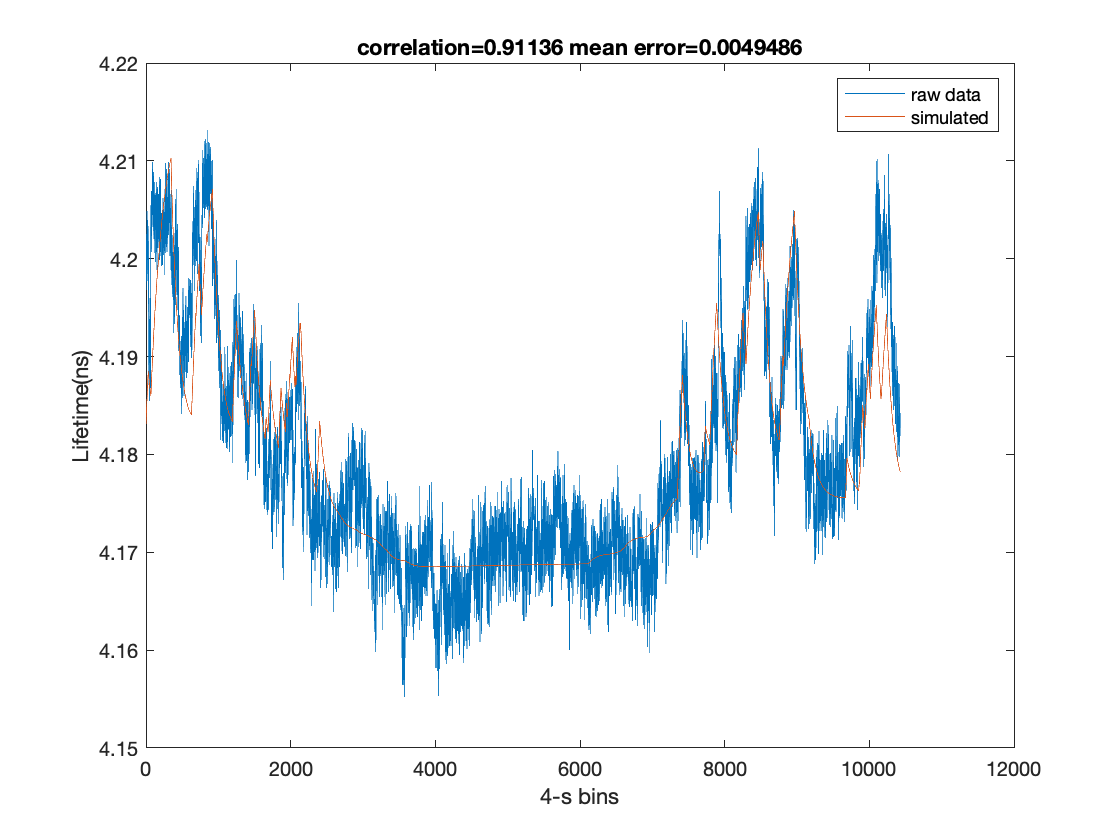

plot_length=length(rawT)/8;
figure
plot(rawT(end-plot_length+1:end))
hold on
plot(simulatedT(end-plot_length+1:end))
xlabel('4-s bins')
ylabel('Lifetime(ns)')
legend('raw data', 'simulated')
title(['correlation=',num2str(correlation),' mean error=',num2str(mean_error)])
saveas(gcf,[Temperature_path,ExperimentName,'.fig'])
saveas(gcf,[Temperature_path,ExperimentName,'.png'])

c=parcluster

c = 

 Local Cluster

    Properties: 

                   Profile: local
                  Modified: false
                      Host: pingchuans-imac
                NumWorkers: 25
                NumThreads: 4

        JobStorageLocation: /Users/pingchuanma/Library/Application Support/MathWorks/MATLAB/local_cluster_jobs/R2021b
   RequiresOnlineLicensing: false

    

j=batch(@example2_Optimization,1,{rawData, OptResults})

j = 

 Job

    Properties: 

                   ID: 53
                 Type: independent
             Username: pingchuanma
                State: running
       SubmitDateTime: 31-Aug-2022 00:49:39
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 4

      AutoAttachFiles: true
  Auto Attached Files: 

sizePWP=[]


sizePWP =

     []



shiftPWP=[]


shiftPWP =

     []



asymptots_L=[];
asymptots_U=[];
TimeConstant_wake=[];
TimeConstant_NREM=[];
scalePWP=[];
circadianAmplitude=[];
circadianPhase=[];

for i=1:4
    eval(['sizePWP=[sizePWP; OptimizedParameters',num2str(i),'.sizePWP];']);
    eval(['shiftPWP=[shiftPWP; OptimizedParameters',num2str(i),'.shiftPWP];']);
    eval(['asymptots_L=[asymptots_L; OptimizedParameters',num2str(i),'.lowerAsymptote];']);
    eval(['asymptots_U=[asymptots_U; OptimizedParameters',num2str(i),'.upperAsymptote];']);
    eval(['TimeConstant_wake=[TimeConstant_wake; OptimizedParameters',num2str(i),'.wakeTimeConstant];']);
    eval(['TimeConstant_NREM=[TimeConstant_NREM; OptimizedParameters',num2str(i),'.nremTimeConstant];']);
    eval(['scalePWP=[scalePWP; OptimizedParameters',num2str(i),'.scalePWP];']);
    eval(['circadianAmplitude=[circadianAmplitude; OptimizedParameters',num2str(i),'.circadianAmplitude];']);
    eval(['circadianPhase=[circadianPhase; OptimizedParameters',num2str(i),'.circadianPhase];']);
end